# EX1_shielding_of_a point_source_with_spherical_shield


%%% evaluation of leakages prob %%%



tic

for ii=1:2000


R=1; %radious of the shield 
sigma=0.5;
pa=0.3;
ps=1-pa;


err=1;
toll=0.01;
i=1;

while err>toll || i<100
    x0=0;y0=0;z0=0;
    vita=1;
    
    while vita==1
        mu=-1+2*rand;
        phi=2*pi*rand;
        l=-1/sigma*log(rand);
        
        x= x0+l*cos(phi)*sqrt(1-mu^2);
        y=y0+l*sin(phi)*sqrt(1-mu^2);
        z=z0+l*mu;
        
        volo=sqrt(x^2+y^2+z^2);
        
        if volo>R 
            %leaked out 
            csi(i)=1;
            vita=0;
        elseif volo<R 
                %still in the medium 
                if rand<pa
                    %particle absorbed 
                    vita=0;
                    csi(i)=0;
                else 
                    vita=1; % not necessary, just as remark 
                    x0=x;y0=y;z0=z;
                    
                end
        end
        
        
    end
    
    
    samp_av_r(i)=sum(csi)/i;
    mom_2_r(i)=sum(csi.^2)/i;
    var_r(i)=mom_2_r(i)-samp_av_r(i)^2;
    RSD_r(i)=sqrt(var_r(i)/i)/samp_av_r(i);
    
    err=RSD_r(i);
    
    
    i=i+1;

    
end

check_CLT_samp_av(ii)=samp_av_r(end);
clear samp_av_r var_r RSD_r csi mom_2_r
  
end

toc 

Elapsed time is 9.084607 seconds.


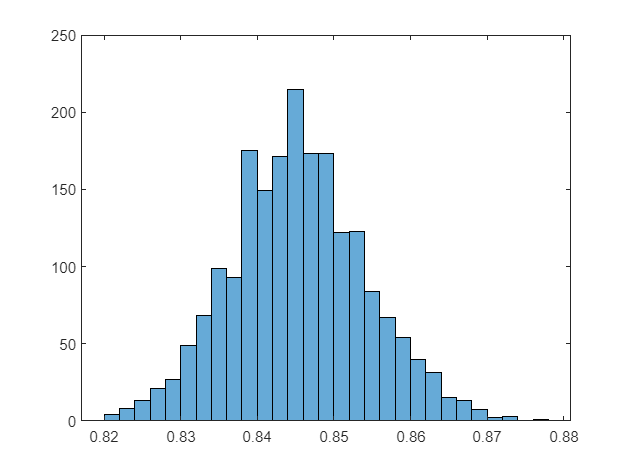

histogram(check_CLT_samp_av)

%plot(samp_av_r)
%plot(RSD_r)




The logical indices contain a true value outside of the array bounds.